# Installation and Quickstart

In this livescript, we will guide you through the installation of EEGLAB and give you information on some important variable types we will use later. 

## Installation

**EEGLAB** is a MATLAB toolbox used for processing data from electroencephalography (EEG), magnetoencephalography (MEG), and other physiological signals (e.g. eye tracking). You can download the toolbox [here](https://eeglab.org/download/). After downloading it, you can place it anywhere you find convenient. Some location suggestions may include the MATLAB directory in your documents, or in the MATLAB toolbox directory. You can type **matlabroot** in the command window to get MATLAB's path, and the **toolbox** directory is located there. Note what the path is to EEGLAB. 

You can either add the path permanently using the Home Tab. Select **Set Path** and **click Add Folder...**. **Select your eeglab toolbox folder** and **click save**. While this may conflict with other toolboxes with functions that have the same name (overloading a function), I have not encountered that problem at all. You can type** eeglab** in your command window, and this should open up the GUI.  

Alternatively, you can add the EEGLAB path before starting any of your EEGLAB scripts using the **addpath** and **genpath **function. You just have to remember to use these functions before using EEGLAB. Afterwards, you should be able to type **eeglab** in your command window and this should open up the GUI. 

Now we need to install several EEGLAB plugins via the GUI. If you haven't done so, open the GUI by typing **eeglab**. Click on file and select **Manage EEGLAB exentions**. 

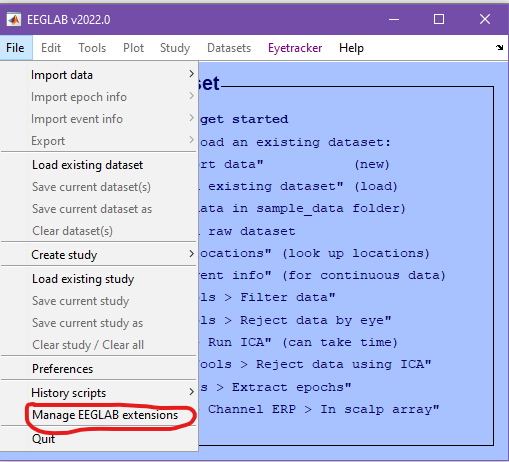

The window of all EEGLAB plugins available to update or install (see below) should open. To load in EEG data from Lab Streaming Layer (LSL) recordings (they are in the extensible data format or XDF), you need to install the latest **xdfimport **plugin. If the **clean_rawdata **plugin isn't installed, please install that as it provides various ways to clean EEG data, including artifact subspace reconstruction. You can explore other plugins if you want to. 

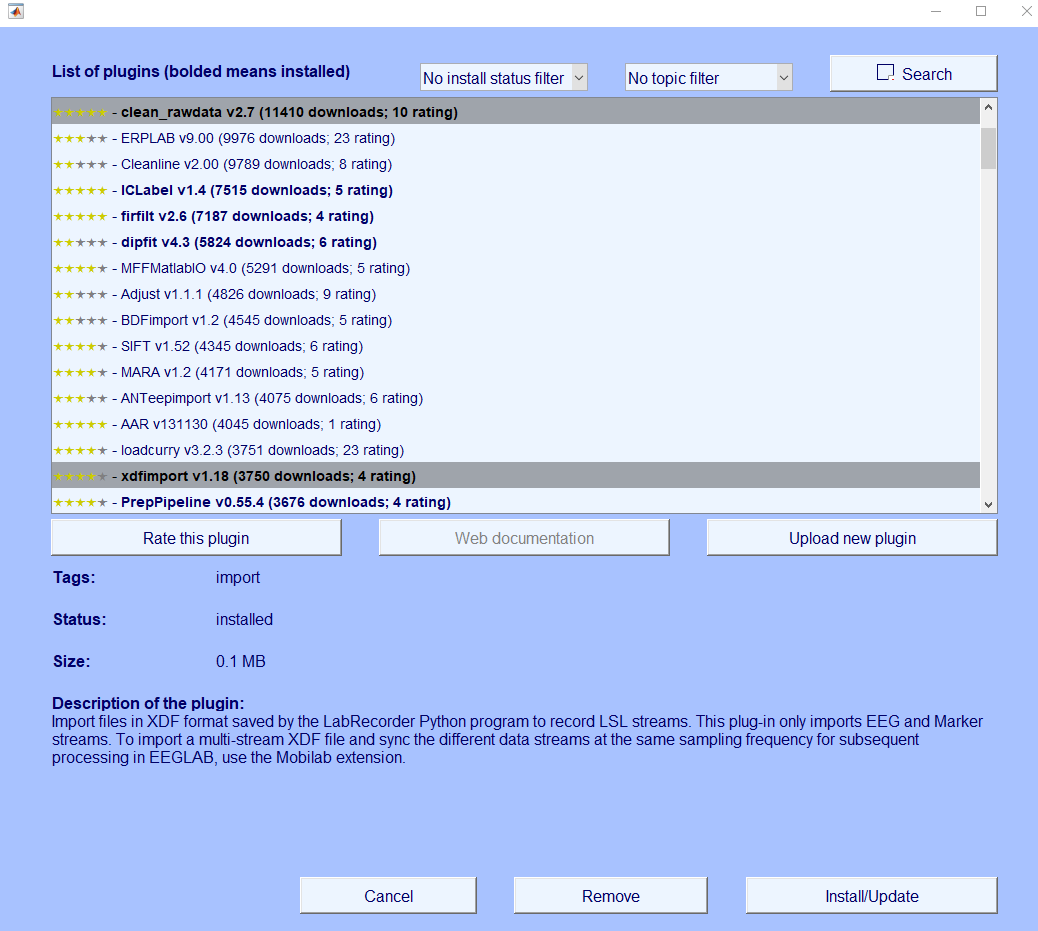

## Important Variable Types

There are three important variable types I commonly use in conjunction with EEGLab: arrays, cell arrays, and structs. It's important you learn what these are as they will be used to manipulate, extract, and analyze data.

**Arrays **can be uni-dimensional or multi-dimensional (vectors or matrices, respectively). They can only hold numerical data (integers or doubles) and are bound by linear algebra operations. By linear algebra operations, we cannot simply multiply any size matrix. For instance, if you are multiplying matrix A by B (A*B), matrix A (m x n) must have the the same number of columns as the number of rows in B (n x m), and matrix A must have the same number of rows as the number of columns in B. This would produce a new matrix of size (n x n). Fortunately, for the most part, you rarely do any matrix/vector operations. **However, arrays are important as our EEG data are organized as multi-dimensional arrays. Unepoched EEG** data have a size of m columns of channels by n rows of samples. For instance, if we have a Biosemi cap with 64 channels sampling at 100Hz for 5 minutes, our EEG data should have 64 rows (one for each channel) and 30,000 columns (100sec-1 * 5min * 60sec/min). This particular array will be two-dimensional. Before explaining epoched data, epoching is a process of dividing our data into discrete chunks of data of a specified size. One example would be epoching your data into 1 second increments. This allows researchers to remove noisy epochs and clean up the data for further analysis. For our previous array example, epoching it would produce 300 one-second epochs (5min*60sec/min). **Epoched data** are three dimensional arrays with size m x n x p where m is the number of channels, n is the number of samples in epochs, and p is the number of epochs. It is also possible that we can epoch data when an event occured (to analyze any event related potentials or ERPs). Knowledge of how EEG data arrays are structured can also help in producing your own plots (rather than relying on EEGlab functions). Please review the code below: 

%Arrays are created by square brackets []
%Here is a row vector (or one dimensional array): 
v1 = [1,2,3,4,5];

%Here is a column vector (still one dimensional): 
v2 = [1;2;3;4;5]; %notice that semicolons create new rows

%Matrices can also be created the same way
%Matrix A will have 2 rows and 3 columns: 
A = [1,2,3;4,5,6];
%Matrix B will have 3 rows and 2 columns:
B = [1,2;3,4;5,6];
%Multiplying them gives us C with 2 rows and 2 columns: 
C = A*B; %The size function gives you the shape of your array. 
fprintf('Matrix C will have %i rows and %i columns',size(C,1),size(C,2));

Matrix C will have 2 rows and 2 columns


%Let's create a 3-dimensional array D with the rand function
D = rand(3,2,4); % this will be a 3 x 2 x 4 array

% 3-dimensional arrays can be a little daunting since we humans really can't
% imagine how a 3D array is structured. Think of the last dimension as the
% number of sheets. In the D array, we have 4 sheets of 3x2 arrays. Let's
% see how to access the first sheet (also notice we use parenthesis to access arrays): 
D(:,:,1) %colons are used to signify we want all rows or columns

ans =     0.8055    0.2399
    0.5767    0.8865
    0.1829    0.0287



%Can you access the 4th sheet of the D array below: 


%How about the second row of the 3rd sheet of the D array below: 


**Cell arrays** can also be uni-dimensional or multi-dimensional, but can store any data type your heart desires (chars, integers, strings, etc). If you have done any Python programming, they can be compared to the mutable list data type. To access the contents of a celll, enclose indices in curly braces ({}). **Cell arrays are important, because they can be used to store our EEG data channel names (e.g. Fp1, Cz, or O1) or any event markers in our data. Moreover, they can be used to find specific EEG channels or events by creating boolean arrays**. The function **contains** is important in doing so. Review the following code:

%Creating a cell array of channel names: 

%Frontal channels: 
frontal_ch = {'F7','F5','F3','F1','Fz','F2','F4','F6','F8'};

%Let's say we want to extract Fz; 
% Rather than accessing 5th element, let's use a boolean array
% Note how we accessed the Fz using the boolean array.
bool_array = contains(frontal_ch,'Fz');
fprintf('We just extracted %s from our frontal_ch cell array',frontal_ch{bool_array});

We just extracted Fz from our frontal_ch cell array


%However, if you want to find more than one element in a cell array, 
% you can also use contain to find a comman pattern

%Let's say we have some events from an event marker stream in our EEG data 
% stored in a cell array. We have two types of events when a visual 
% stimuli was displayed: standard and deviant
events = {'standard_01','deviant_01','standard_02','deviant_02',...
    'standard_03','deviant_03','standard_04','deviant_04'};

%What do we do to extract only elements that contain a deviant event? 
% We can use a boolean array: 
bool_array = contains(events,'deviant');
events_deviant = {events{bool_array}};
disp('Here are all the deviant events in a cell array: ')

Here are all the deviant events in a cell array: 


events_deviant

events_deviant = 1×4 cell array
    {'deviant_01'}    {'deviant_02'}    {'deviant_03'}    {'deviant_04'}



%Can you access the standard_03 event in the events cell array 
% using the contains function?

%How about only standard events? 


Our arrays are only uni- or multi-dimensional matrices that we can access its content with basic indexing. Each row contains data from a specific channel, so how do we store data that contains channel names that correspond to what row. Channel names are part of an EEG dataset. We also have time stamps for each data point as well as event marker information (and their associated timestamps). How do we organize our data so that we can easily access? It would be cumbersome to store each of these related data streams as cell arrays. This is what a **structure array **or **struct** comes in. A struct is a data type that groups related data using data containers called *fields*, which can be any type of data. These data can be accessed using dot notation (e.g. structName.fieldName). You can store data with descriptive keys that correspond to the kind of data you want to store. This is the variable type EEGlab uses to store EEG subject data. Let's load in a dataset and explore the EEG struct. For now, you can ignore how we loaded in the data. We will go over how to load data in the next tutorial. You have to load eeglab, so please uncomment the method of how you installed eeglab.

%Change this to the path where eeglab folder is
%eeglab_path = fullfile(matlabroot,'toolbox','eeglab');
%addpath(genpath(eeglab_path));

%Initializing EEGlab
%eeglab;

%Load in a sample EEG data set
dir_xdf = fullfile('data','xdf');
file_name = 'vrcct_p4_prestudy_condition.xdf';
file_path = fullfile(dir_xdf,file_name);
EEG = pop_loadxdf( ...
    file_path);

Now importing...

done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs



%Access EEG data using the data fieldname:
disp('10 EEG data points from all channels: ')

10 EEG data points from all channels: 


disp(EEG.data(:,1:10));

   1.0e+05 *

    5.8708    5.8708    5.8708    5.8708    5.8708    5.8708    5.8708    5.8708    5.8708    5.8708
   -0.1924   -0.1924   -0.1925   -0.1927   -0.1924   -0.1921   -0.1921   -0.1921   -0.1921   -0.1922
   -0.1002   -0.1001   -0.1002   -0.1000   -0.1000   -0.0999   -0.0999   -0.0998   -0.0999   -0.1001
   -0.2223   -0.2222   -0.2223   -0.2223   -0.2223   -0.2222   -0.2223   -0.2222   -0.2222   -0.2223
   -0.0416   -0.0416   -0.0416   -0.0415   -0.0415   -0.0415   -0.0415   -0.0415   -0.0415   -0.0415
   -0.2207   -0.2206   -0.2207   -0.2206   -0.2206   -0.2206   -0.2206   -0.2205   -0.2205   -0.2206
   -0.0833   -0.0833   -0.0834   -0.0833   -0.0832   -0.0833   -0.0833   -0.0832   -0.0832   -0.0833
   -0.0618   -0.0618   -0.0618   -0.0617   -0.0616   -0.0616   -0.0617   -0.0616   -0.0616   -0.0617
   -0.1385   -0.1384   -0.1385   -0.1384   -0.1384   -0.1385   -0.1384   -0.1383   -0.1382   -0.1383
   -0.0923   -0.0923   -0.0923   -0.0922   -0.0921   -0.0921   -0.0922   -0.0

num_channels = size(EEG.data,1);
num_dataPoints = size(EEG.data,2);
fprintf( ...
    'This EEG dataset has %i channel(s) and %i datapoints.', ...
    num_channels,num_dataPoints); 

This EEG dataset has 73 channel(s) and 291697 datapoints.


%Access EEG channel labels using the chanlocs and labels fieldnames:
chan_labels = {EEG.chanlocs.labels}; %Save labels as cell array
disp('The channel labels associated with each row of our data are ')

The channel labels associated with each row of our data are 


disp(chan_labels)

  Columns 1 through 17

    {'Trig1'}    {'A1'}    {'A2'}    {'A3'}    {'A4'}    {'A5'}    {'A6'}    {'A7'}    {'A8'}    {'A9'}    {'A10'}    {'A11'}    {'A12'}    {'A13'}    {'A14'}    {'A15'}    {'A16'}

  Columns 18 through 33

    {'A17'}    {'A18'}    {'A19'}    {'A20'}    {'A21'}    {'A22'}    {'A23'}    {'A24'}    {'A25'}    {'A26'}    {'A27'}    {'A28'}    {'A29'}    {'A30'}    {'A31'}    {'A32'}

  Columns 34 through 50

    {'B1'}    {'B2'}    {'B3'}    {'B4'}    {'B5'}    {'B6'}    {'B7'}    {'B8'}    {'B9'}    {'B10'}    {'B11'}    {'B12'}    {'B13'}    {'B14'}    {'B15'}    {'B16'}    {'B17'}

  Columns 51 through 66

    {'B18'}    {'B19'}    {'B20'}    {'B21'}    {'B22'}    {'B23'}    {'B24'}    {'B25'}    {'B26'}    {'B27'}    {'B28'}    {'B29'}    {'B30'}    {'B31'}    {'B32'}    {'EX1'}

  Columns 67 through 73

    {'EX2'}    {'EX3'}    {'EX4'}    {'EX5'}    {'EX6'}    {'EX7'}    {'EX8'}




%We can extract the A11 Channel data with a boolean array:
bool_array = contains(chan_labels,'A11');
disp('15 EEG data points from A11 channel')

15 EEG data points from A1 channel


disp(EEG.data(bool_array,1:15))

   1.0e+03 *

   -8.5757   -8.5771   -8.5788   -8.5679   -8.5624   -8.5631   -8.5710   -8.5646   -8.5630   -8.5715   -8.5717   -8.5665   -8.5610   -8.5559   -8.5639




%Access its event markers (We will go over these more in depth later)
% using the event and type fieldnames:
events = {EEG.event.type};
disp('Here are all the events in the EEG dataset: ')

Here are all the events in the EEG dataset: 


disp(events(:))

    {'Left trigger pressed'  }
    {'Right trigger pressed' }
    {'Start meditation audio'}
    {'Right trigger released'}
    {'Left trigger released' }
    {'Left trigger pressed'  }
    {'Right trigger pressed' }




%Access its sampling rate using the srate fieldname
fprintf('The EEG data was sampled at %d Hz',EEG.srate)

The EEG data was sampled at 512 Hz

## **Final Exercises**

This final section will provide exercises using all the above things you learned in the previous sections. I have provided comments that point to the section where you can find how to perform the task. You will use the previous EEG struct for these excercises. Use the disp to display your results

%Final Excercises: 

% 1. Create a boolean array to find the 'B16' channel of our EEG struct 
% Refer to Line 39 in Cell Arrays and Line 87 in Struct

% 2. Extract the data of the 'B16' channel from the EEG struct using the
% boolean array in the first excercise
% Refer to 92-94 in Struct

% 3. How many samples are in our extracted EEG data
% Refer to Line 81 in Struct

% 4. Approximately how many seconds did we record EEG
% We will explore how we can get this data easily in a later lesson
% Refer to Line 103 in Struct; Tip: Divide number of samples by
% sampling rate

% 5. From the EEG event markers, extract the index (using find) for the 
% the 'Start meditation audio' event. Use the function "find" to find the
% index (e.g. find(contains(...)))
% Refer to Line 98 in Struct

## **Conclusion**

EEGlab can be installed very easily and can be opened by typing eeglab in the command window. There are three important data types that each have its uses in EEGlab: arrays, cell arrays, and structs. This should be a little primer on each of these data types, but feel free to research further. Subsequent tutorials will provide instructions on how to access EEG structs and what information we can access with it, how to preprocess EEG data, how to epoch data, how to extract/plot event related potentials (ERPs), and many more useful analysis pipelines. While it may be a bit (or a lot) overwhelming, these lessons can be copied/modified to fit your research goal. For instance, an automated preprocessing pipeline can created pretty easily using these tutorials that you can use in most experimental paradigms. Hopefully, you learn lots and can write your own analysis scripts in the end. Let me know if you have any questions or want the solutions to the excercises. 